**Parameters**

% M matrix -> it's symmetric
m1 = 96.8;
m2 = -3.57;
m3 = -3.57;
m4 = 0.258;

% C matrix
c1 = 0;
c2 = -50.8;
c3 = 0.436;
c4 = 2.20;

% K0 matrix
k11 = -901.0;
k12 = 35.17;
k13 = 35.17;
k14 = -12.03;

% K2 matrix
k21 = 0;
k22 = -87.06;
k23 = 0;
k24 = 3.50;

V = 3.5;

**State Space representation**

a1 = k11+k21*V^2;
a2 = k12+k22*V^2;
a3 = k13+k23*V^2;
a4 = k14+k24*V^2;

A1 = m2/(m2*m3-m1*m4);
A2 = m4/m2;
A3 = m1/m2;

A = [
    0                                     0                             1                               0;
    0                                     0                             0                               1;
    A1*A2*a1-A1*a3                     A1*A2*a2-A1*a4                 A1*A2*c1*V-A1*c3*V                  A1*A2*c2*V-A1*c4*V;
    -A1*A2*A3*a1+A1*A3*a3-a1/m2     -A1*A2*A3*a2+A1*A3*a4-a2/m2     -A1*A2*A3*c1*V+A1*A3*c3*V-c1*V/m2     -A1*A2*A3*c2*V+A1*A3*c4*V-c2*V/m2;
];

B = [
    0;
    0;
    A1;
    -A3*A1
];

C = [1 0 0 0];
D = 0;

sys_ss = ss(A, B,C,D)

sys_ss =
 
  A = 
            x1       x2       x3       x4
   x1        0        0        1        0
   x2        0        0        0        1
   x3    8.741    12.75  -0.4455    1.503
   x4   -15.36    56.91   -12.08   -9.045
 
  B = 
           u1
   x1       0
   x2       0
   x3  0.2919
   x4   7.915
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



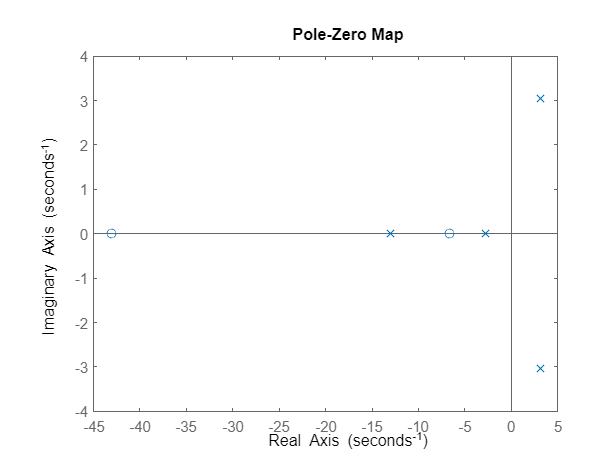

pzmap(sys_ss)

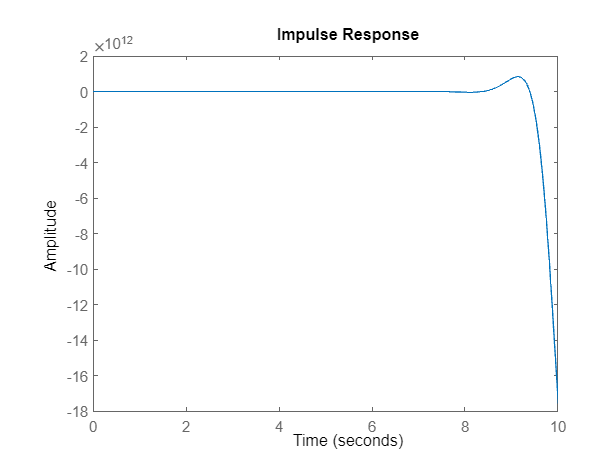

impulse(sys_ss)

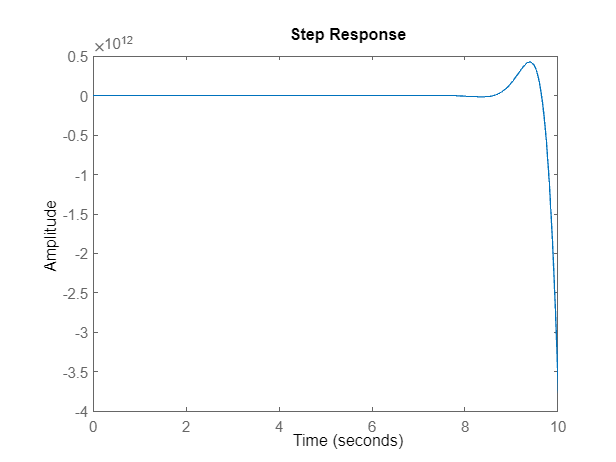

step(sys_ss)

eig(A)

ans =    3.1367 + 3.0396i
   3.1367 - 3.0396i
  -2.8048 + 0.0000i
 -12.9589 + 0.0000i


**transfer function**

[tf_num, tf_denum] = ss2tf(A,B,C,D)

tf_num =          0         0    0.2919   14.5386   84.3301


tf_denum =     1.0000    9.4903  -43.4668   72.7186  693.4056


sys_tf = tf(tf_num, tf_denum)

sys_tf =
 
          0.2919 s^2 + 14.54 s + 84.33
  --------------------------------------------
  s^4 + 9.49 s^3 - 43.47 s^2 + 72.72 s + 693.4
 
Continuous-time transfer function.



pole(sys_tf)

ans =  -12.9589 + 0.0000i
   3.1367 + 3.0396i
   3.1367 - 3.0396i
  -2.8048 + 0.0000i


**Lyapunov method for stability analysis**

Q = eye(length(A))

Q =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


P = lyap(A,Q)

P =     0.5245    0.0440   -0.5000    0.6443
    0.0440   -0.2645   -0.6443   -0.5000
   -0.5000   -0.6443   -7.3753    6.6309
    0.6443   -0.5000    6.6309  -10.5323


eig(P)

ans =   -15.8107
   -2.4430
    0.0379
    0.5683


if all(eig(P) > 0)
    disp('The system is stable.')
else
    disp('The system is not stable.')
end

The system is not stable.


**Controllability and Observability**

obsy = obsv(sys_ss.A, sys_ss.C);
conty = ctrb(sys_ss.A, sys_ss.B);

rank(conty)

ans = 4

ans = 4

rank(obsy)
if rank(obsy) == length(sys_ss.A)
    disp('The system is observable.')
else
    disp('The system is not observable.')
end

The system is observable.


if rank(conty) == length(sys_ss.A)
    disp('The system is controllable.')
else
    disp('The system is not controllable.')
end

The system is controllable.


if rank(obsy) == length(A) && rank(conty) == length(A)
    disp('This realization is minimal.')
else
    disp('This realization is not minimal.')
end

This realization is minimal.


## **Designing Controller and Observer**

pole(sys_ss)

ans =    1.1109 + 4.7325i
   1.1109 - 4.7325i
  -1.7465 + 0.0000i
 -14.3039 + 0.0000i


**Pole placement**

new_poles = [
  -2 -5+6i -5-6i -10
]

new_poles =   -2.0000 + 0.0000i  -5.0000 + 6.0000i  -5.0000 - 6.0000i -10.0000 + 0.0000i


K = place(A,B,new_poles)

K =    10.1625   16.5977    2.5350    0.9388



A_pp = A-B*K;
B_pp = B;
C_pp = C;
D_pp = D;

sys_ss_pp = ss(A_pp, B_pp, C_pp, D_pp);
sys_ss_pp

sys_ss_pp =
 
  A = 
           x1      x2      x3      x4
   x1       0       0       1       0
   x2       0       0       0       1
   x3   5.775   19.12  -1.389   1.916
   x4   -95.8    -106  -37.67  -20.61
 
  B = 
           u1
   x1       0
   x2       0
   x3  0.2919
   x4   7.915
 
  C = 
       x1  x2  x3  x4
   y1   1   0   0   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



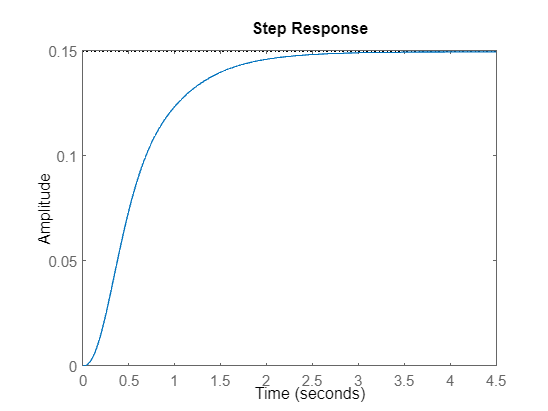

step(sys_ss_pp)

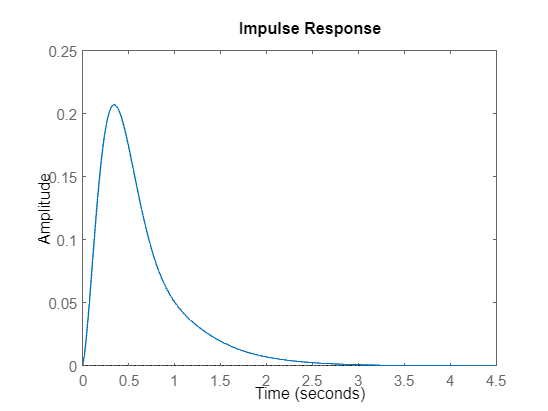

impulse(sys_ss_pp)

eig(A_pp)

ans =  -10.0000 + 0.0000i
  -5.0000 + 6.0000i
  -5.0000 - 6.0000i
  -2.0000 + 0.0000i


% observer_poles -> roughly 2 times faster than fastest poles of the State FB
observer_poles = [-20, -20, -20, -20];
L_t = acker(A', C', observer_poles);
L = L_t'

L = 1.0e+03 *

    0.0662
    0.4701
    1.4720
   -0.1946


A_obs = A-L*C

A_obs = 1.0e+03 *

   -0.0662         0    0.0010         0
   -0.4701         0         0    0.0010
   -1.4632    0.0240   -0.0006    0.0022
    0.1793    0.0254   -0.0176   -0.0132


B_obs = [B L] % input is [u Y]'

B_obs = 1.0e+03 *

         0    0.0662
         0    0.4701
    0.0003    1.4720
    0.0079   -0.1946


C_obs = eye(length(A_obs)) % since we want all the states

C_obs =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


D_obs = zeros(size(B_obs))

D_obs =      0     0
     0     0
     0     0
     0     0
